# Gradient Descent

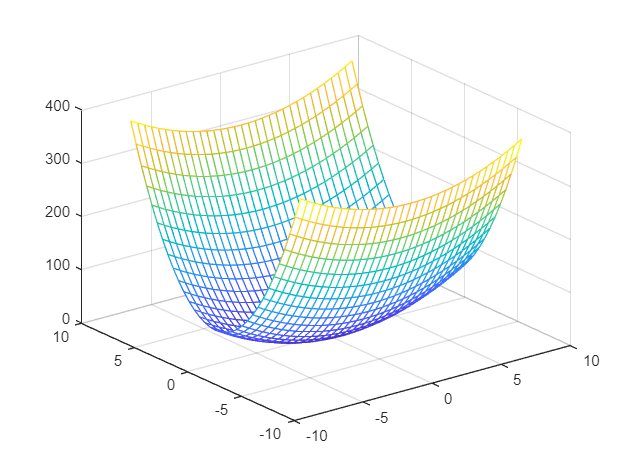

clear;clc;

[X1,X2] = meshgrid(-8:.5:8);
Z = X1.^2 + 5*X2.^2;
mesh(X1,X2,Z)

cost_z = @(x) x(1)^2 + 5*x(2)^2;

## Gradient Descend

alpha = 0.001;
grad_z = @(x) [2*x(1);10*x(2)];

x = [5;1];
prev_x = rand(2,1);
while norm(prev_x-x)>10e-9
    prev_x = x;
    gradient = grad_z(x);
    x = x - alpha*gradient;    
end

x

x = 1.0e-05 *

    0.4988
    0.0000


## GD with Backtrack Line Search

beta = 0.9;
mu = 0.4;
x = [5;1];
prev_x = rand(2,1);
while norm(prev_x-x)>10e-9
    prev_x = x;
    gradient = grad_z(x);
    alpha = 1;
    while cost_z(x-alpha*gradient) > cost_z(x) - mu*alpha*norm(gradient)^2
        alpha = beta*alpha;
    end
%     disp(alpha);
    x = x - alpha*gradient;
end

x

x = 1.0e-07 *

    0.1067
   -0.0286


## GD with Exact Line Search

x = [5;1];
prev_x = rand(2,1);
while norm(prev_x-x)>10e-9
    prev_x = x;
    gradient = grad_z(x);
    alpha = (x(1)*gradient(1)+5*x(2)*gradient(2))/cost_z(gradient); % Analytic gradient
%     disp(alpha);
    x = x - alpha*gradient;
end

x

x = 1.0e-07 *

    0.1176
   -0.0235
